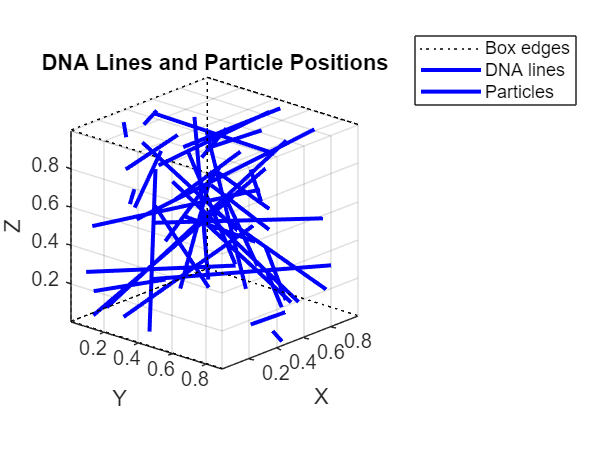

% Read the whole file as strings
lines = readlines("C:\Users\admin\Desktop\CylinderRust\Data.txt");

% Find the lines where "DNA" and "Particles start" are mentioned
dna_start = find(lines == "DNA") + 1;
particles_start = find(lines == "Particles start") + 1;

% Extract the DNA lines
dna_lines = lines(dna_start : particles_start - 2); % until the line before "Particles start"
dna_data = sscanf(join(dna_lines, newline), '%f,%f,%f,%f,%f,%f');
DNA = reshape(dna_data, 6, []).';  % Nx6 matrix: [x y z dx dy dz]
if size(DNA, 2) ~= 6
    DNA = reshape(DNA, [], 6);  % Force 6 columns
end

% Extract the particle lines
particle_lines = lines(particles_start : end);
particle_data = sscanf(join(particle_lines), '%f,%f,%f\n');
Particles = reshape(particle_data, 3, []).';  % Mx3 matrix: [x y z]

% Plotting parameters
figure;
hold on;
axis equal;
xlabel('X'); ylabel('Y'); zlabel('Z');
xlim([0 1]); ylim([0 1]); zlim([0 1]);
grid on;
view(3);

% Plot cube boundaries (optional wireframe)
plot3([0 1 1 0 0 0 1 1 0 0 0 1 1 1 0 0], ...
      [0 0 1 1 0 0 0 1 1 0 0 0 0 1 1 1], ...
      [0 0 0 0 0 1 1 1 1 1 0 0 1 1 1 0], 'k:');

% Plot the DNA lines
for i = 1:size(DNA, 1)
    point = DNA(i, 1:3);
    direction = DNA(i, 4:6);

    t = linspace(-5, 5, 100);
    line_pts = point + t' .* direction;

    in_bounds = all(line_pts >= 0 & line_pts <= 1, 2);
    line_pts = line_pts(in_bounds, :);

    plot3(line_pts(:,1), line_pts(:,2), line_pts(:,3), 'b', 'LineWidth', 2);
end

% Plot the particles
%scatter3(Particles(:,1), Particles(:,2), Particles(:,3), 20, 'r', 'filled');
hold off
title('DNA Lines and Particle Positions');
legend('Box edges', 'DNA lines', 'Particles');


clear i lines t line_pts dna_start particles_start particle_data

clc
clear
% Import the data
TTDmatrix = readmatrix("C:\Users\admin\Desktop\CylinderRust\TTD.txt");

height = size(TTDmatrix, 1)

height = 1

width = size(TTDmatrix,2)

width = 100000

TTDx = linspace(0,width,width);
clear opts
TTDx = TTDx(2:end);

% Constants
deltax = 1/100;

deltax = 0.0100

deltay = 1/100;

deltay = 0.0100

deltaz = 1/100;

deltaz = 0.0100

D_3d = (deltax^2 + deltay^2 + deltaz^2) / 6; %Skal justeres med 3d.
r_int = 0.05;
%n = 1000;
n = 1;
V = 1;
N = 2;
k_nson = 0.1; %FORKERT VÆRDI, SKAL ÆNDRES TIL DEN RIGTIGE!
l_dna = 1; %N / B^3 eller volumen af linjestykker.

% Inverse Laplace Transform using Talbot method
K0 = @(s) besselk(0, sqrt(s / D_3d) * r_int);
K1 = @(s) besselk(1, sqrt(s / D_3d) * r_int);
K_1_div_K_0 = @(s) K1(s) ./ K0(s);



l_dna = 1

J_cap = @(s) k_nson * l_dna / s^2 * (1+k_nson * K0(s) /(2 * pi * sqrt(s *D_3d) * r_int * K1(s)))^(-1)

J_cap = function_handle with value:
    @(s)k_nson*l_dna/s^2*(1+k_nson*K0(s)/(2*pi*sqrt(s*D_3d)*r_int*K1(s)))^(-1)


TalbotInverse = @(t) Talbot(J_cap, t, 8);
TalbotInverse_array = arrayfun(TalbotInverse,TTDx);

P_survival = exp(-TalbotInverse_array).^N

P_survival =     0.9948    0.9925    0.9906    0.9890    0.9875    0.9862    0.9849    0.9837    0.9826    0.9815    0.9805    0.9795    0.9785    0.9776    0.9767    0.9758    0.9749    0.9741    0.9732    0.9724    0.9716    0.9708    0.9700    0.9693    0.9685    0.9678    0.9670    0.9663    0.9656    0.9649    0.9642    0.9635    0.9628    0.9621    0.9615    0.9608    0.9602    0.9595    0.9589    0.9582    0.9576    0.9570    0.9563    0.9557    0.9551    0.9545    0.9539    0.9533    0.9527    0.9521


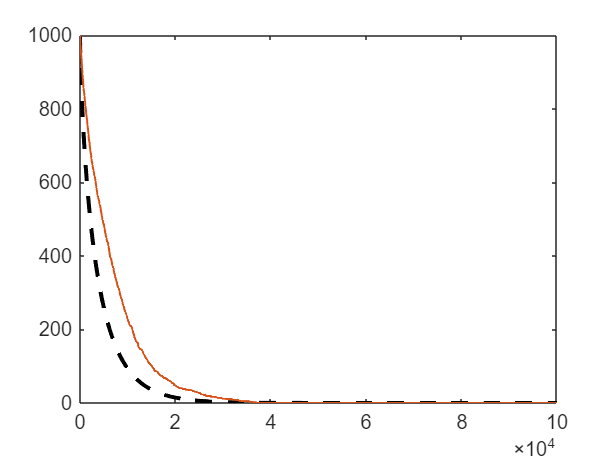


%P_survival_values = arrayfun(P_survival,TTDx);

figure();
plot(TTDx,(P_survival * 1000), color='black', LineStyle="--", LineWidth=2);
hold on
for i = 1:height
TTD = TTDmatrix(i,2:end);
plot(TTDx,(1000-TTD), LineWidth=1);
end
hold off


%Skriv om til periodske randbetingelser.
%Prøv med flere/færre targets.
%Test bindingslogik.